clear variables
tic
N = 6080; v = 10; w = 10.001; xi = 7;
e0 = 0.0; T1 = 0.1; dlt = 0;%0.05; 
NN = 10;
psol = linspace(1,49,25);
el_oc = zeros([length(psol) NN]);
for j = 1:length(psol)
    for ii = 1:NN
        [H, sol] = solSSH(N, v, w, e0, dlt, T1, xi, psol(j));
        [V, D] = eig(H);
        n00 = 0;
        for n = 1:length(sol)
            % Replace the inner loop with a matrix operation
            n00 = n00 + sum(V(N+n, 1:N/2).^2, 'all');
        end
        el_oc(j,ii) = n00;
    end
    j
end
noc = el_oc ./ (2*psol' + 1);
save sol_met_tst.mat noc psol el_oc v w e0 xi dlt

toc

The electron occupancy is given zero for most of the solitons. This is because the Fermi level is set to 0 (or N/2), such that the half of solitons energy  are "above" the fermi level. Note that the electron occupancy is not set by energy, but the total number of electrons available in the SSH chain, wich at half filling, it is N/2.

## Section for plots: off-resonance

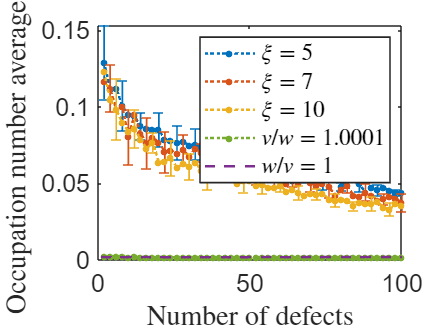

clear all
% After loading the data:
figure; hold on;
% Add labels and legend
xlabel('Number of defects','Interpreter','latex');
ylabel('Occupation number average $\overline{n}_0$','Interpreter','latex');
legend('Interpreter','latex');
lineWidth = 1.5;
fontSize = 15;
blueColor = [0, 0.4470, 0.7410];
redColor = [0.85,0.33,0.10];
yellowColor = [0.93,0.69,0.13];
purpleColor = [0.49,0.18,0.56];
greenColor = [0.4660 0.6740 0.1880];
% Set font size of axes (tick labels and axis labels)
set(gca, 'FontSize', fontSize);
% Set box properties
box on; 
set(gca, 'LineWidth', 1);
% % -------------------- xi = 5 -----------------------------------------
load('xxi5T.mat')
moc = mean(noc,2); nnoc = moc(1:3:end);
A1 = std(noc,0,2); A = A1(1:3:end);
ppsol1 = psol; ppsol = ppsol1(1:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = blueColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$\xi = 5$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), '-o', 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$\xi = 5$');
errorbar(2.*ppsol,nnoc,A, '.', 'Color', blueColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')
% % -------------------- xi = 7 -----------------------------------------
load('xxi7T.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = redColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$\xi = 7$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', redColor, 'LineWidth', lineWidth, 'DisplayName', '$\xi = 7$');
errorbar(2.*ppsol,nnoc,A,'.', 'Color', redColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')
% % -------------------- xi = 10 -----------------------------------------
load('xxi10T.mat')
moc = mean(noc,2); nnoc = moc(3:3:end);
A1 = std(noc,0,2); A = A1(3:3:end);
ppsol1 = psol; ppsol = ppsol1(3:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = yellowColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$\xi = 10$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', yellowColor, 'LineWidth', lineWidth, 'DisplayName', '$\xi = 10$');
errorbar(2.*ppsol,nnoc,A, '.', 'Color', yellowColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')
% % -------------------- Metallic ----------------------------------------
% load('xxi7M.mat')
% plot(2.*psol,mean(noc,2),'--', 'Color', purpleColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1$');
% xlim([0 100])

% % ------------------- Metallic trivial defects -----------------------
load('off_sol_met.mat')
moc = mean(noc,2); nnoc = moc(3:3:end);
A1 = std(noc,0,2); A = A1(3:3:end);
ppsol1 = psol; ppsol = ppsol1(3:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = greenColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$v/w = 1.0001$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', yellowColor, 'LineWidth', lineWidth, 'DisplayName', '$\xi = 10$');
errorbar(2.*ppsol,nnoc,A, '.', 'Color', greenColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('trvl_dfct.mat')
plot(def,mean(noc,2),'--', 'Color', purpleColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1$');
xlim([0 100])


% % Solitons1 has the standar deviation in the same (every 2) cites for all
% the curves.
% % Solitons2 changes the standar deviation cite for the red line (xi =
% 10), such that it has more space to see
% % Soliton3 does not have the second plot (red one) with xi = 10
% % Solitons4 is the same as Solitons3 but shifting for the place of the
% standar deviation for xi = 10


## Resonance Effects

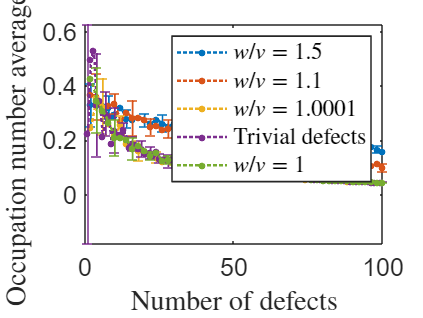

figure; hold on;
% Add labels and legend
xlabel('Number of defects','Interpreter','latex');
ylabel('Occupation number average $\overline{n}_0$','Interpreter','latex');
legend('Interpreter','latex');
lineWidth = 1.5;
fontSize = 15;
blueColor = [0, 0.4470, 0.7410];
redColor = [0.85,0.33,0.10];
yellowColor = [0.93,0.69,0.13];
purpleColor = [0.49,0.18,0.56];
greenColor = [0.4660 0.6740 0.1880];
% Set font size of axes (tick labels and axis labels)
set(gca, 'FontSize', fontSize);
% Set box properties
box on;
set(gca, 'LineWidth', 1);

% load('xxi7T_e0.mat')
load('w15_resonance.mat')
moc = mean(noc,2); nnoc = moc(1:3:end);
A1 = std(noc,0,2); A = A1(1:3:end);
ppsol1 = psol; ppsol = ppsol1(1:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = blueColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1.5$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', blueColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('w11_resonance.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = redColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1.1$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', redColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('sol_met.mat')
moc = mean(noc,2); nnoc = moc(3:3:end);
A1 = std(noc,0,2); A = A1(3:3:end);
ppsol1 = psol; ppsol = ppsol1(3:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = yellowColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1.0001$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', yellowColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('res_trvl_dfct.mat')
psol = linspace(1,100,100);
moc = mean(noc,2); nnoc = moc(1:3:end);
A1 = std(noc,0,2); A = A1(1:3:end);
ppsol1 = psol; ppsol = ppsol1(1:3:end);
p = plot(psol,mean(noc,2));
p.LineStyle = ":";
p.Color = purpleColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "Trivial defects";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(ppsol,nnoc,A,".", 'Color', purpleColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')


load('metallic_resonance.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = greenColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', greenColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

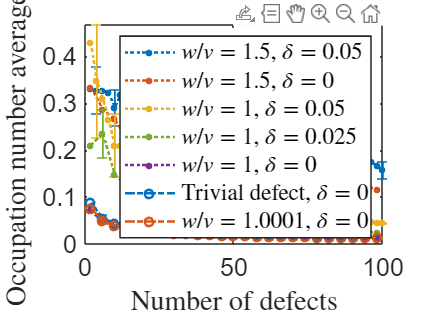


figure; hold on;
% Add labels and legend
xlabel('Number of defects','Interpreter','latex');
ylabel('Occupation number average $\overline{n}_0$','Interpreter','latex');
legend('Interpreter','latex');
lineWidth = 1.5;
fontSize = 15;
blueColor = [0, 0.4470, 0.7410];
redColor = [0.85,0.33,0.10];
yellowColor = [0.93,0.69,0.13];
purpleColor = [0.49,0.18,0.56];
greenColor = [0.4660 0.6740 0.1880];
% Set font size of axes (tick labels and axis labels)
set(gca, 'FontSize', fontSize);
% Set box properties
box on;
set(gca, 'LineWidth', 1);

load('w15_resonance.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = blueColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1.5$, $\delta=0.05$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', blueColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('top_tst.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = redColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1.5$, $\delta=0$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', redColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('metallic_resonance.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = yellowColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1$, $\delta=0.05$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', yellowColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('met_tst2.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = greenColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1$, $\delta=0.025$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', greenColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('met_tst.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = ":";
p.Color = purpleColor;
p.LineWidth = lineWidth;
p.Marker = ".";
p.DisplayName = "$w/v = 1$, $\delta=0$";
p.MarkerSize = 12;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', purpleColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')

load('res_trvl_dfct_tst.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = "-.";
p.Color = blueColor;
p.LineWidth = lineWidth;
p.Marker = "o";
p.DisplayName = "Trivial defect, $\delta = 0$";
p.MarkerSize = 5;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', blueColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')


load('sol_met_tst.mat')
moc = mean(noc,2); nnoc = moc(2:3:end);
A1 = std(noc,0,2); A = A1(2:3:end);
ppsol1 = psol; ppsol = ppsol1(2:3:end);
p = plot(2.*psol,mean(noc,2));
p.LineStyle = "-.";
p.Color = redColor;
p.LineWidth = lineWidth;
p.Marker = "o";
p.DisplayName = "$w/v = 1.0001$, $\delta = 0$";
p.MarkerSize = 5;
% plot(2.*psol,mean(noc,2), 'Color', blueColor, 'LineWidth', lineWidth, 'DisplayName', '$w/v = 1.5$');
errorbar(2.*ppsol,nnoc,A,".", 'Color', redColor, 'LineWidth', 1, 'HandleVisibility','off', 'DisplayName', 'Line 1')